# Barbara Klaudel

# **The impact of filters on training a neural network to classify computed tomography images of kidney tumors**

### Aplikacja do wizualizacji działania nakładania filtrów na obraz tomografii komputerowej (CT).

For each filter, we tested how well it enhances a CT image with the following metrics.

- **Mean Squared Error (MSE)**

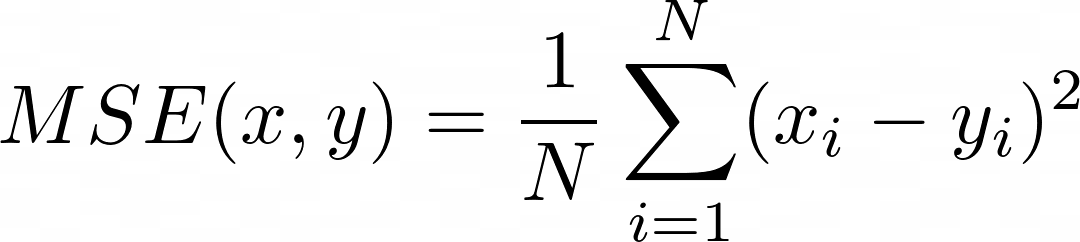  

xi, yi - 2 finite discrete signals (2 images)

N - the number of signal samples, e.g. 130x130 = 16900

**Benefits of MSE: **low computational complexity (1 x multiplication and 2 x addition per sample), low memory usage (MSE can be computed independently for each sample), easy to interpret (MSE=0 -> x=y, MSE(x, y) = MSE(y, x) -> symmetry), good for optimization (symmetric convex differentiable functiun).

**Drawbacks: **it doesn't take into account the order of samples, assumes the quality of signal isn't influenced by the correlation between original and error signal, assumes all samples are equally important.

- **peak-signal-to-noise-ratio (PSNR)**

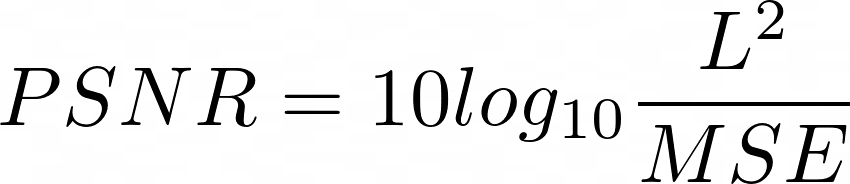

L - the range of acceptable pixel values, i.e. 256

PSNR is helpful when we compare images with different Ls, otherwise it is no more informative than MSE.

- **Structural Similarity Index Measure (SSIM)**

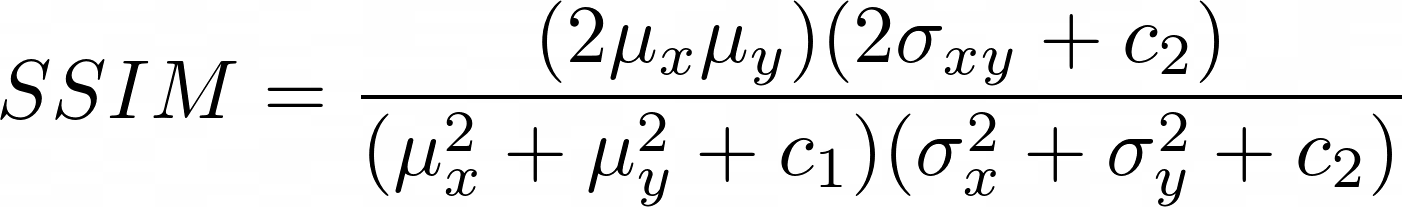

μ- mean value, σ - variance/covariance

SSIM takes the value from rnge -1 to 1 (1 means images are identical) 

Benefits: it takes into account that image signals are highly structured and there is a strong relationship among neighbors that store significant information about the structure and eelements of an image, it gives better results for unstructural disturbances than structural, it is symmetrical SSIM(x, y) = SSIM(y, x), it is somewhat alike to human eye assessment.

Drawbacks: sensitive to translation, scaling and rotation of images.

Based on: Mean Squared Error: Love It or Leave It? IEEE SIGNAL PROCESSING MAGAZINE [100] JANUARY 2009

- We load a sample image. It is a fragment of CT image abdominal cavity presenting a kidney with benigh tumor - angiomyolipoma (AML).

pwd

ans = '/home/basia/Documents/Filtry/filtry_barbara_klaudel'

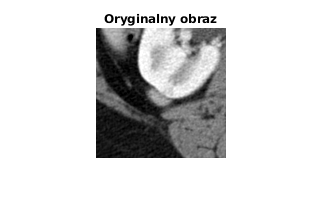


I = imread('/home/basia/Documents/Filtry/filtry_barbara_klaudel/www.png');
imshow(I);
title('Original image');

**Sobel Gradient Filter**

sobelGradient = uint8(imgradient(I));
mse = immse(sobelGradient, I)

mse = 8.8994e+03

ssme = ssim(sobelGradient, I)

ssme = 0.0225

[peaksnr, snr] = psnr(sobelGradient, I);
peaksnr

peaksnr = 8.6372

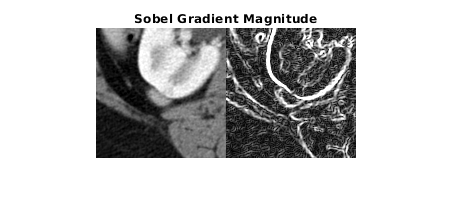

imshowpair(I, sobelGradient, 'montage');
title('Sobel Gradient Magnitude');

**Gradient Magnitude and Direction**

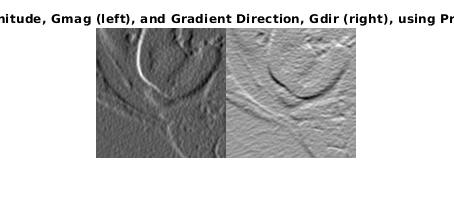

[Gx,Gy] = imgradientxy(I);
imshowpair(Gx, Gy, 'montage');
title('Gradient Magnitude, Gmag (left), and Gradient Direction, Gdir (right), using Prewitt method')

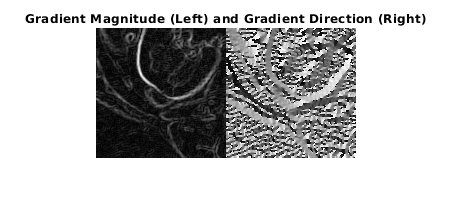

[Gmag, Gdir] = imgradient(I,'prewitt');
imshowpair(Gmag,Gdir,'montage')
title('Gradient Magnitude (Left) and Gradient Direction (Right)')

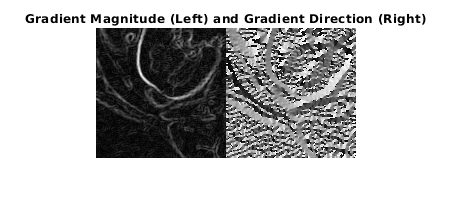

[Gmag, Gdir] = imgradient(I,'sobel');
imshowpair(Gmag,Gdir,'montage')
title('Gradient Magnitude (Left) and Gradient Direction (Right)')

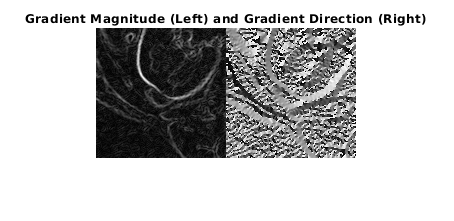

[Gmag, Gdir] = imgradient(I,'central');
imshowpair(Gmag,Gdir,'montage')
title('Gradient Magnitude (Left) and Gradient Direction (Right)')

**Smooth Gradient**

sigma = 2;
smoothImage = imgaussfilt(I,sigma);
smoothGradient = imgradient(smoothImage,'CentralDifference');
mse = immse(smoothImage, I)

mse = 136.3212

ssme = ssim(smoothImage, I)

ssme = 0.7157

[peaksnr, snr] = psnr(smoothImage, I);
peaksnr

peaksnr = 26.7852

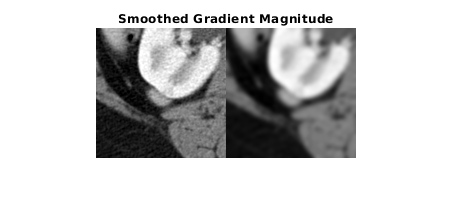

imshowpair(I, smoothImage, 'montage');
title('Smoothed Gradient Magnitude');

## Anisotropic Diffusion (Perona & Malik)

**Anisotropic diffusion with default parameters**

- Often used with CT images

- It sharpens areas, which are borders of an image. It smoothes the insides of areas.

- High diffusion value is desired in homogenous regions. In inhomogenous regions (the regions with high gradient values) low diffusion is desired.

- A space-variant diffusion factor is used to differentiate insides and borders of regions.

ad = imdiffusefilt(I);
mse = immse(ad, I)

mse = 45.4299

ssme = ssim(ad, I)

ssme = 0.8202

[peaksnr, snr] = psnr(ad, I);
peaksnr

peaksnr = 31.5574

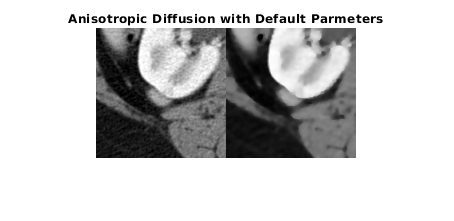

imshowpair(I, ad, 'montage');
title('Anisotropic Diffusion with Default Parmeters')

**Anisotropic diffusion with estimated parameters**

- We can choose from exponential and quadratic methods. Exponential method is suggested if there is strong contrast on the borders, while quadratic method, when we have a lot of homogenous regions.

- We choose optimal number of iteration and gradient treshold value with imdiffuseest matlab function. Gradient treshold value designates the starting value from which we assume that a region is a border.

[gradThresh,numIter] = imdiffuseest(I,'ConductionMethod','quadratic');
ade = imdiffusefilt(I,'ConductionMethod','quadratic', ...
    'GradientThreshold',gradThresh,'NumberOfIterations',numIter);
mse = immse(ade, I)

mse = 41.8651

ssme = ssim(ade, I)

ssme = 0.8545

[peaksnr, snr] = psnr(ade, I);
peaksnr

peaksnr = 31.9123

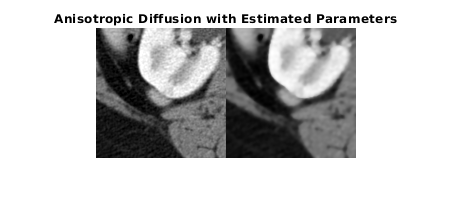

imshowpair(I, ade, 'montage');
title('Anisotropic Diffusion with Estimated Parameters')

**Sharpen Image**

- it uses a method of unsharp masking, which subtracts the blurred image ffrom the original image. The procedure goes as follows:

- Detect edges and create a mask.

-  Use the mask to enhance contrast around the edges.

To simplify: the filter sort of "overdoes" function values in place of light and dark edges.

Check a nice visualization at: https://www.cambridgeincolour.com/tutorials/unsharp-mask.htm

sharpen = imsharpen(I);
mse = immse(sharpen, I)

mse = 21.7911

ssme = ssim(sharpen, I)

ssme = 0.9611

[peaksnr, snr] = psnr(sobelGradient, I);
peaksnr

peaksnr = 8.6372

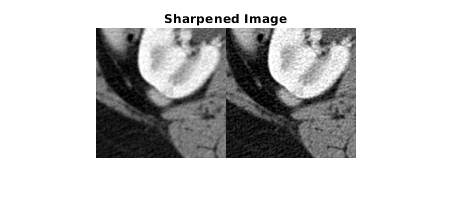

imshowpair(I,sharpen,'montage')
title('Sharpened Image');

**Wiener Filter**

- most commonly used for deconvolution and noise reduction

- often used to enhance the soft tissue areas, e.g. a cyst consisting of connective tissue

- it uses value of local mean and variance independently for each pixel.

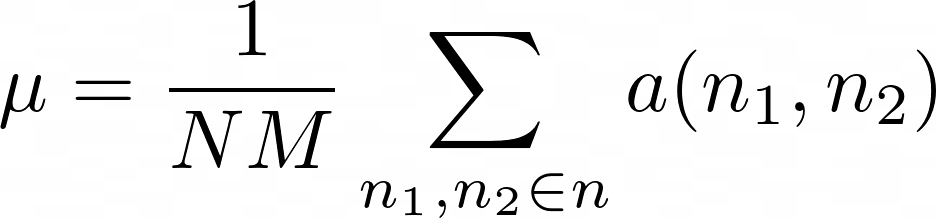    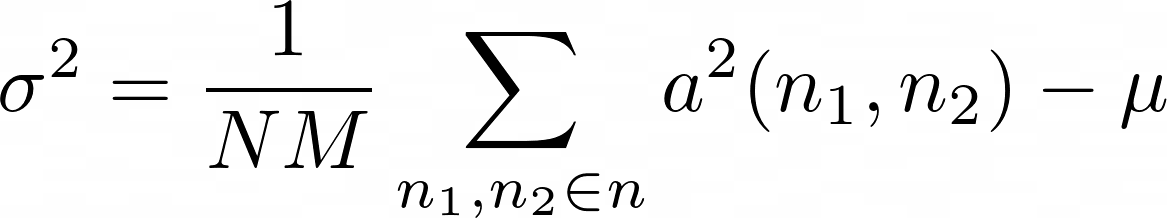

η -  local neighborhood of a pixel with a value N by M

Based on mean and varince, Wiener filter is created, separately for each pixel.

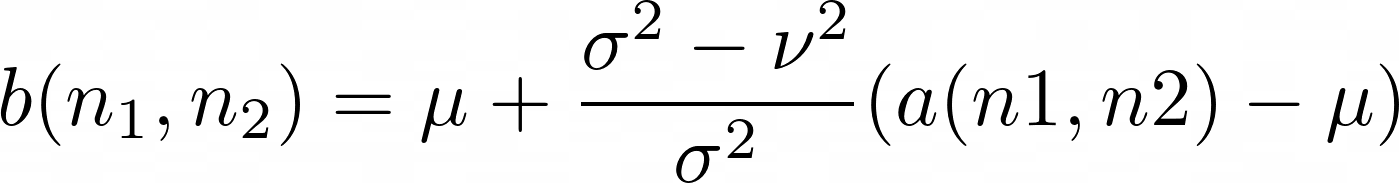

ν^2 - noise variance, if uknown it is estimated based on mean value of all local variances

K = wiener2(I,[5 5]);
mse = immse(K, I)

mse = 66.6433

ssme = ssim(K, I)

ssme = 0.7659

[peaksnr, snr] = psnr(K, I);
peaksnr

peaksnr = 29.8932

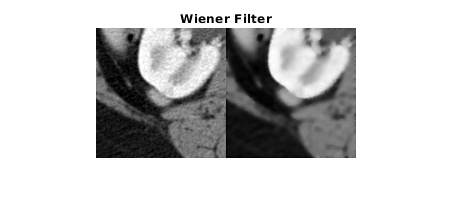

imshowpair(I, K, 'montage');
title('Wiener Filter');

**Transfer Learning**

We checked if applying a filter improves the accuracy of kidney tumor classification. We checked sharpen, Wiener and anisotropic diffusion with esitmated parameters.

We used the dataset of CT images of abdominal cavity collected for TITAN project (https://titan.radiato.ai/). Images come from St. Adalbert's hospital in Gdańsk and from publicly available dataset KITS19. The images present kidney tumors of 6 types: 3 malignant (clear cell renal cell carcinoma (ccRCC), chromophobe renal cell carcinoma (chRCC), papillary renal cell carcinoma (pRCC)) and 3 benign (angiomyolipoma (AML), oncocytoma, benign-other). The dataset consists of middle slices of arterial phase. Multiple slices from the same study where used insteasd of data augmentation.

The images present a kidney with a tumor. The image size is 130x130 pixels. After cropping, the images were converted to png from DICOM wiyh abdominal cavity window.

We used VGG-16 model pretrained on ImageNet. We used 80-20 validation split.

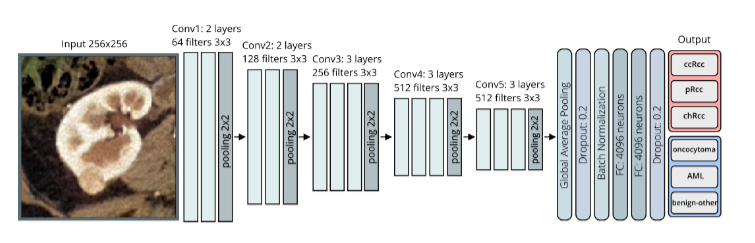

Architecture visualization - source: Aleksander Obuchowski, unpublished research

- **Basic dataset - no filters.**

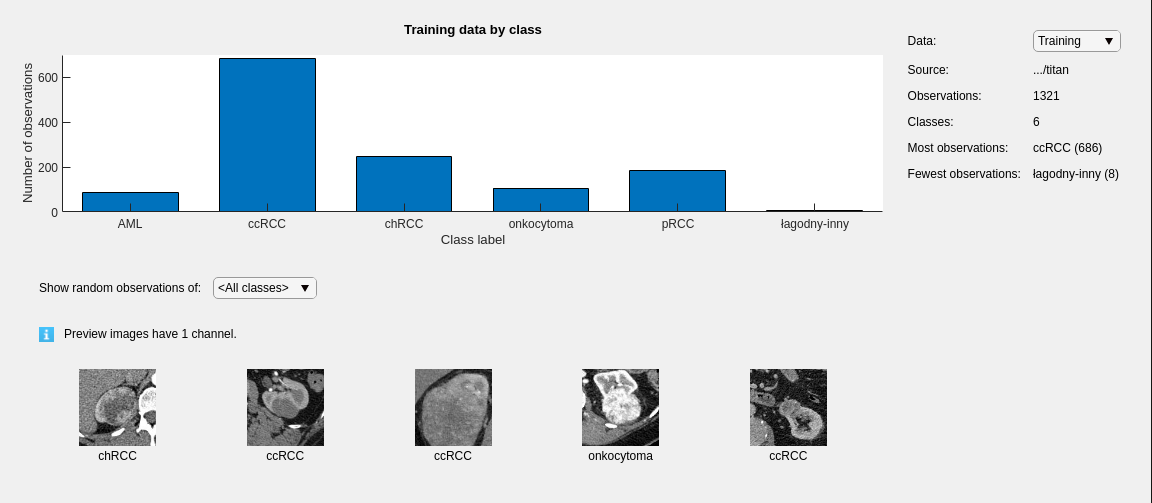

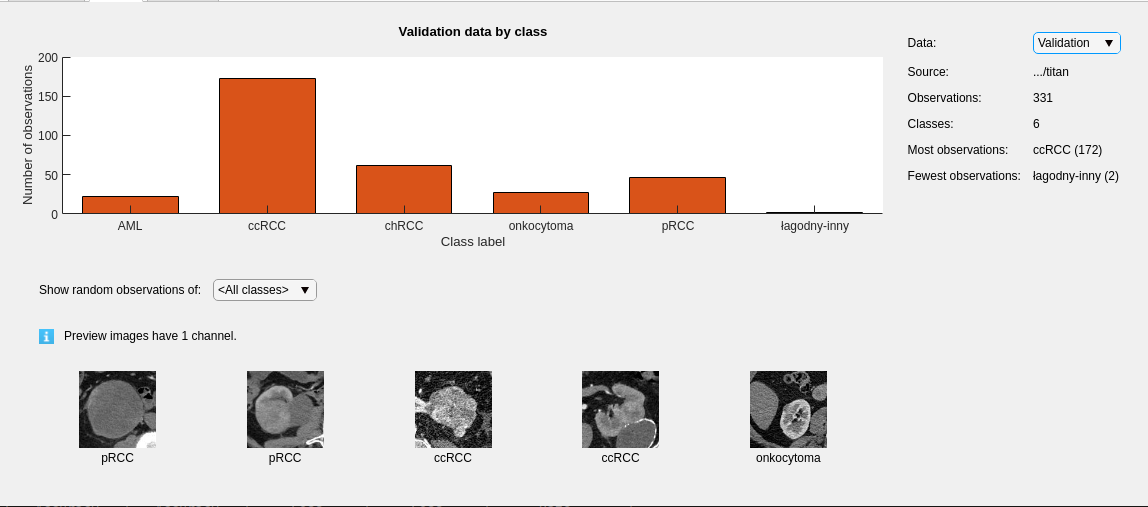

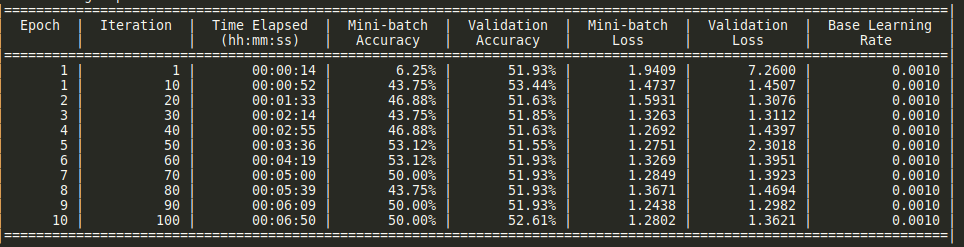

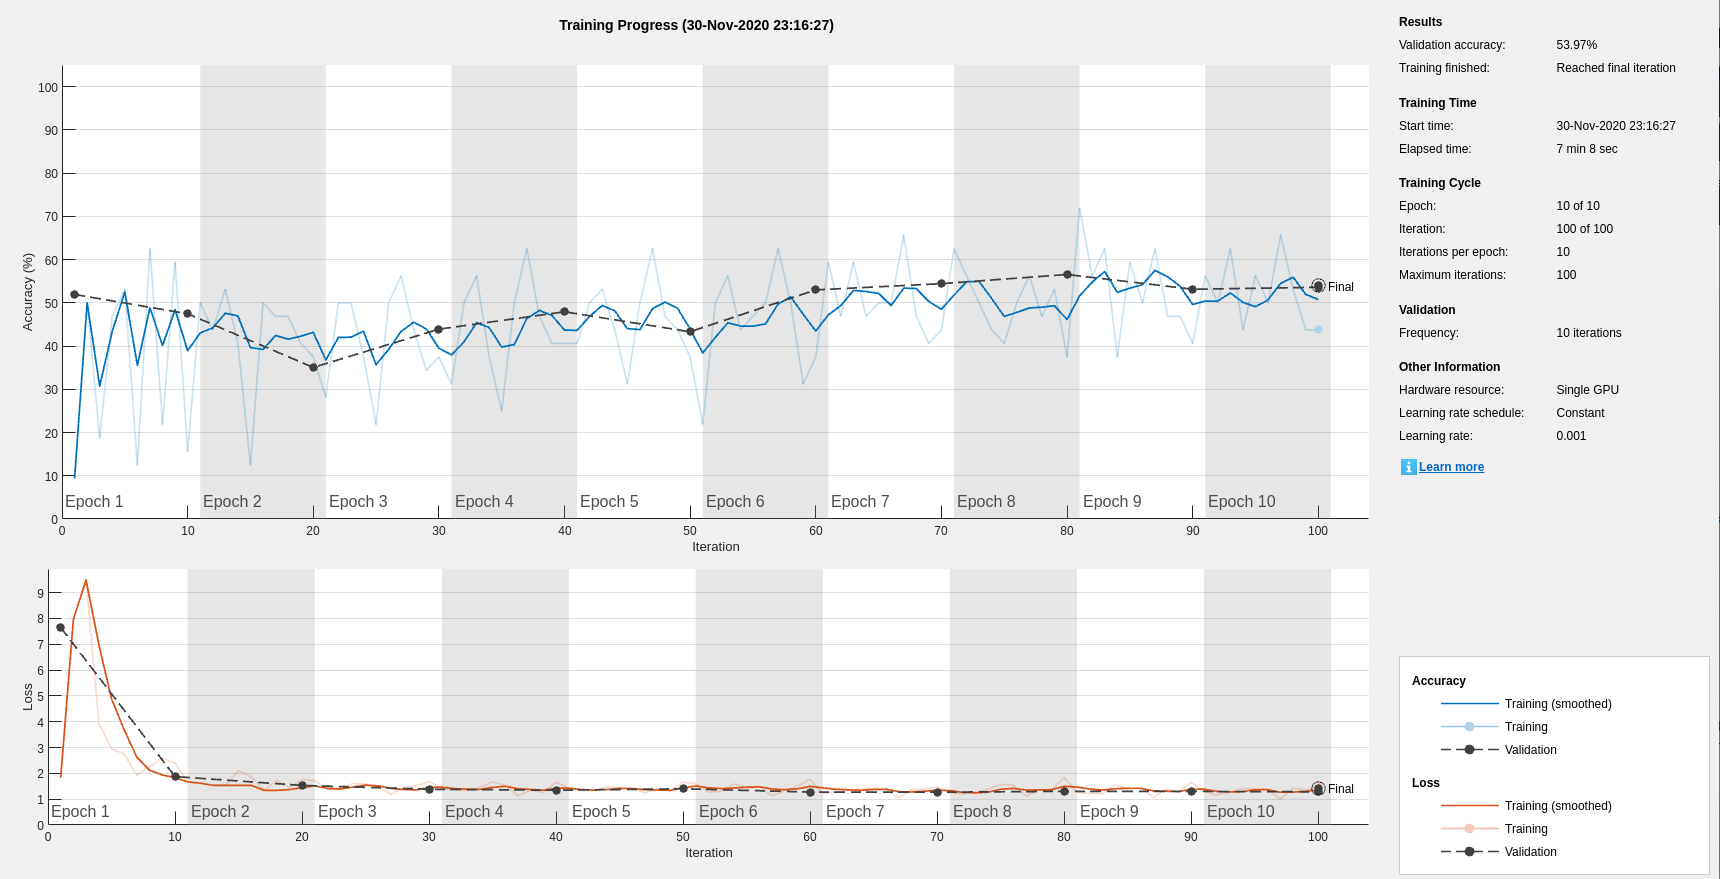

2. Dyfuzja anizotropowa z oszacowanymi parametrami

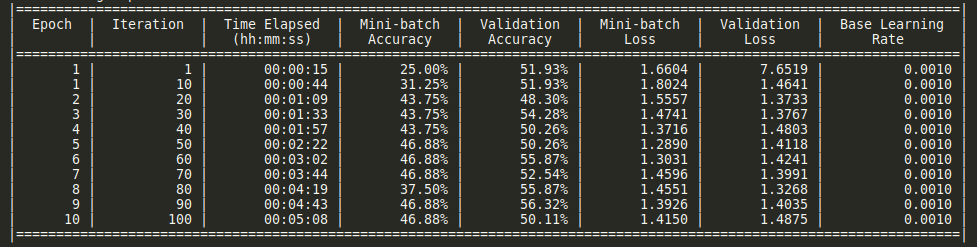

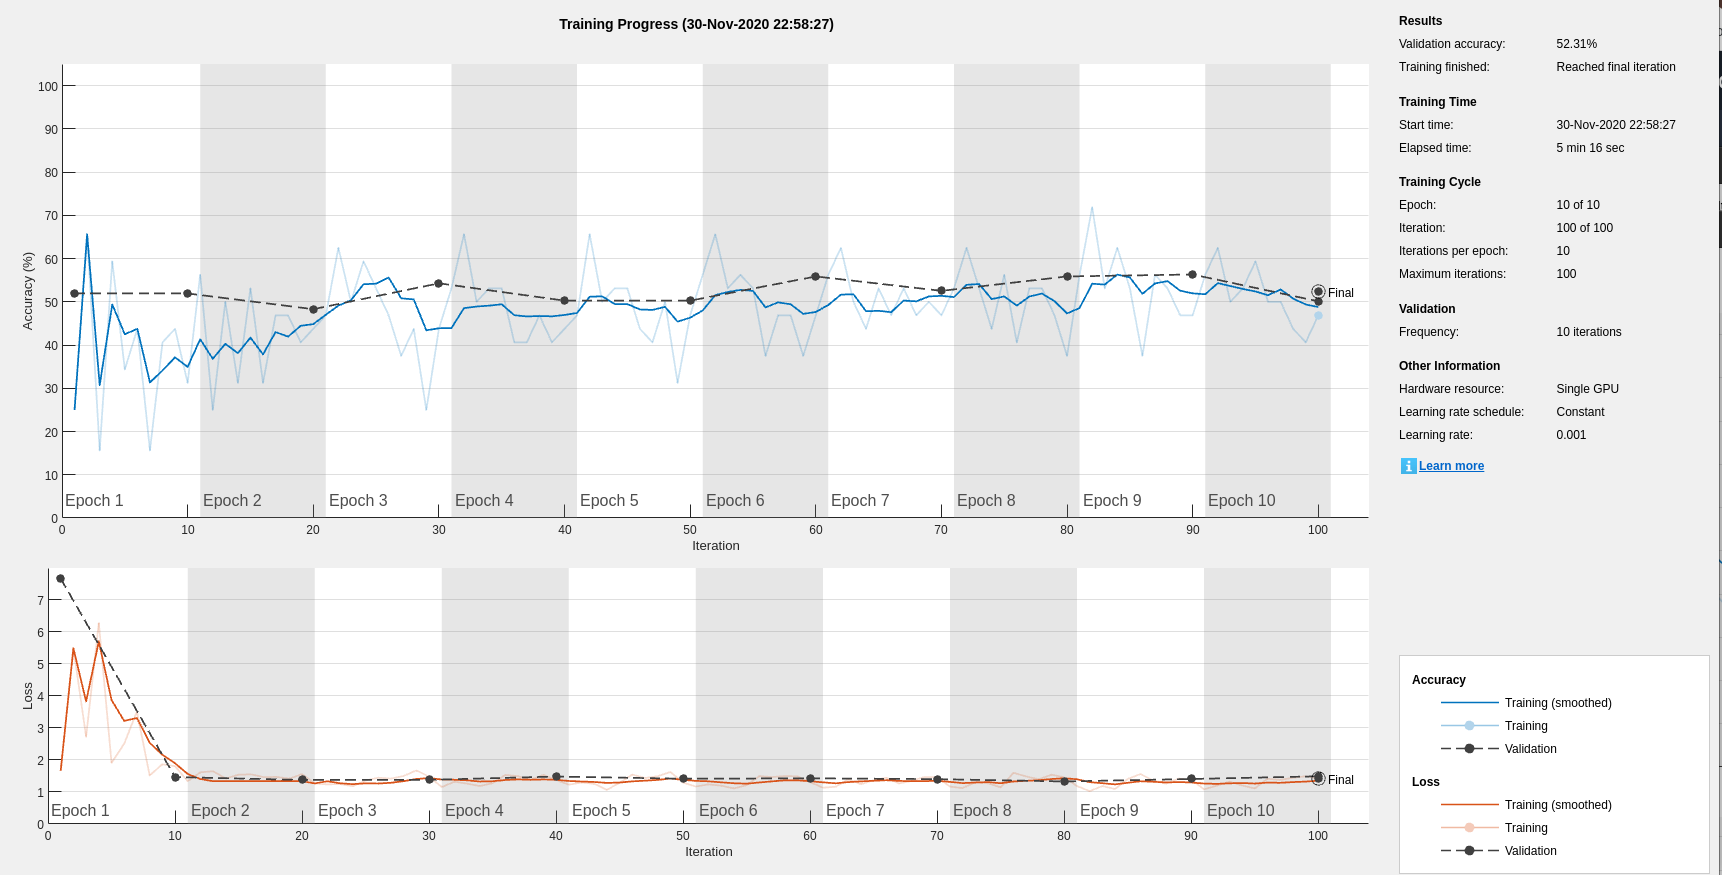

**3. Filtr wyostrzający.**

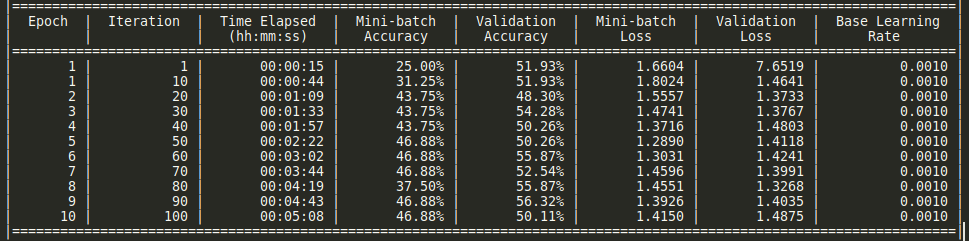

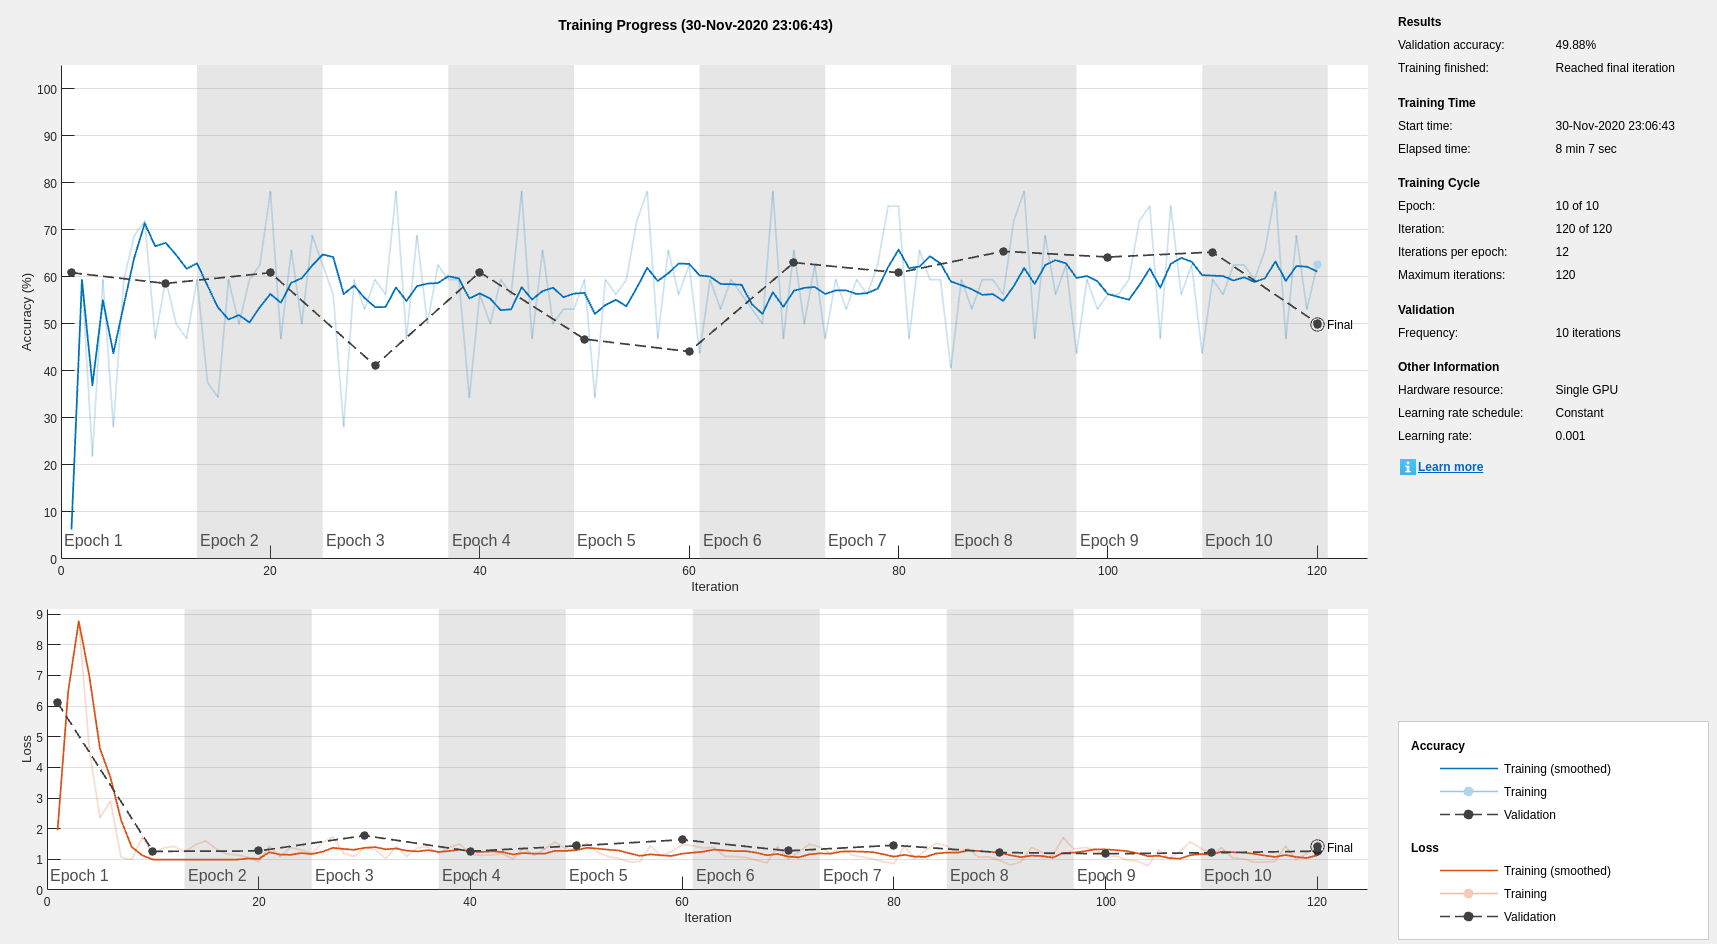

**4. Filtr Wienera.**

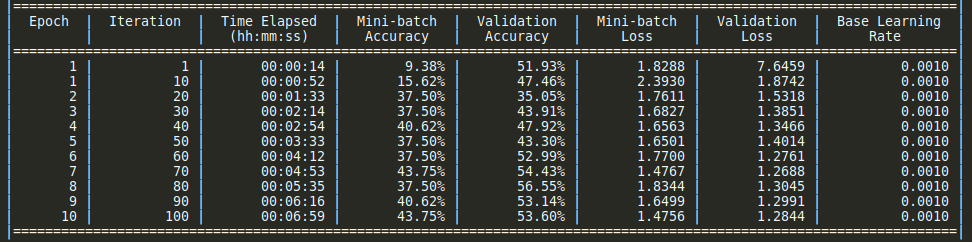

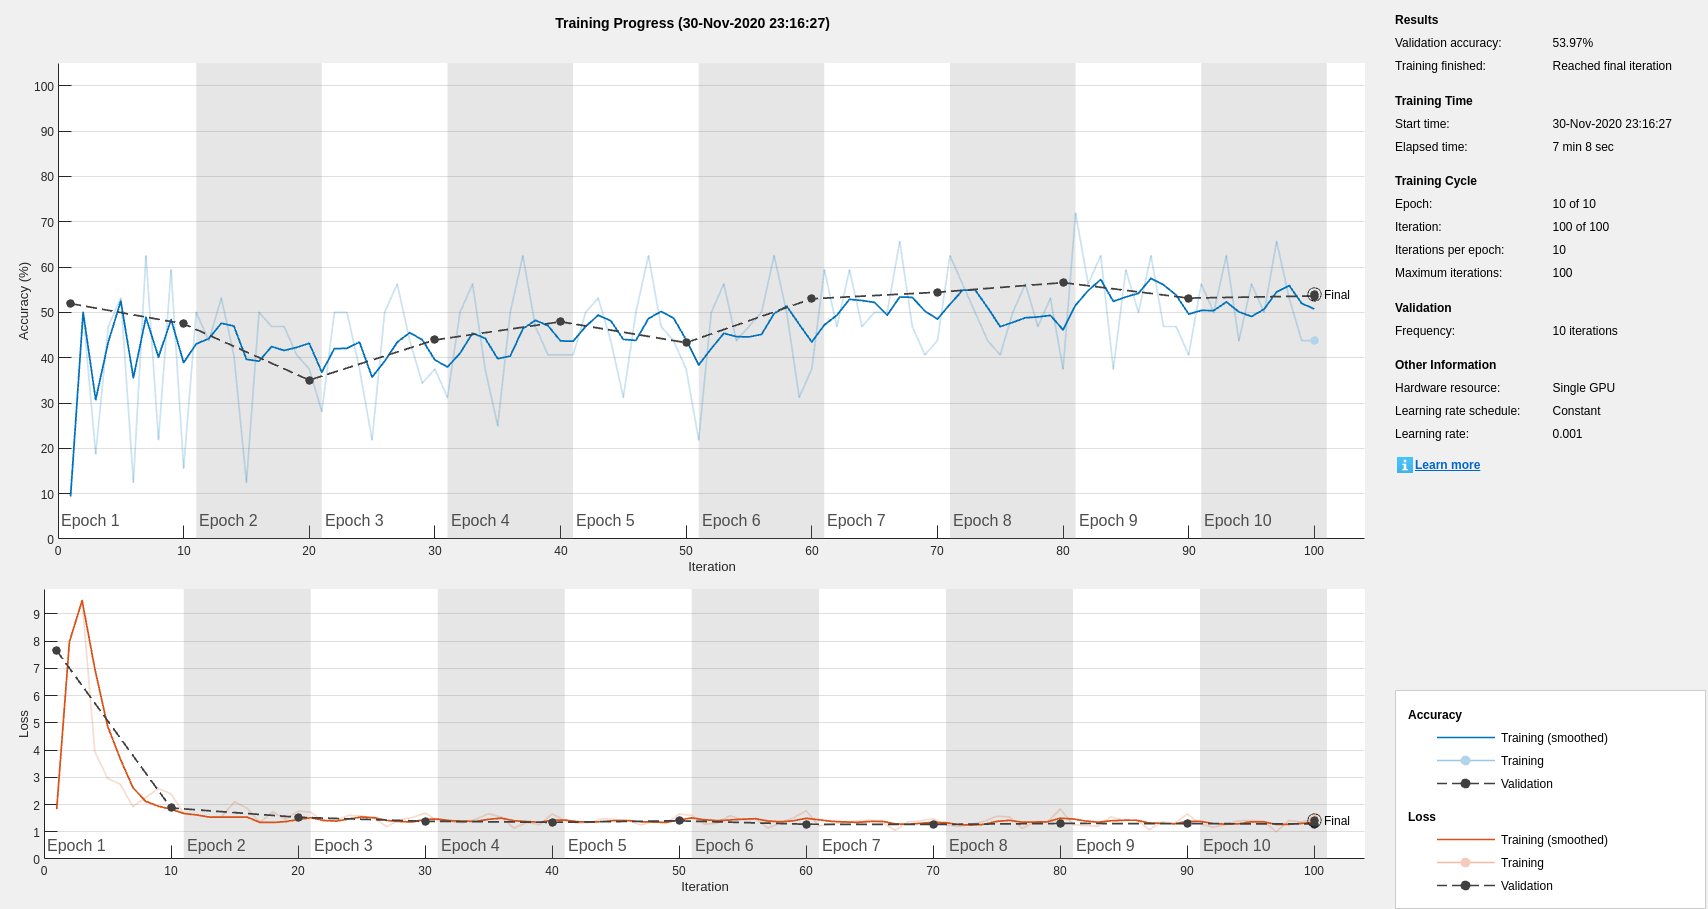

**CONCLUSIONS**

The sharpen filter turned out to give the best results. It improved accuracy on validation datased by a few percentage points.

Anisotropic diffusion improved the results only slightly.

Wiener filter gave results comparable to the unfiltered data.